**Exercise 1**

Solve the pendulum ODE by the intuitive method.


$$\begin{array}{l}
\ddot{\theta} =-\frac{g}{l}\;\sin \;\theta \;\\
\theta_{n+1} =\theta_n +h\;\dot{\theta_n } \\
\dot{\theta_{n+1} } =\dot{\theta_n } +h\;\ddot{\theta_n } \\
\dot{\theta_{n+1} } =\dot{\theta_n } +h\;\left(-\frac{g}{l}\;\sin \;\theta_n \right)
\end{array}$$


Use $L = 2$ and $g = 9.8$ and initial values:


$$\theta_0 = 0.5 rad$$



$$\dot{\theta}_0 = 0 rad/s$$


Solve for $t = 0 \ldots 10s$ with Forward Euler and find a suitable timestep $h$ by trial and error. Animate the pendulum.

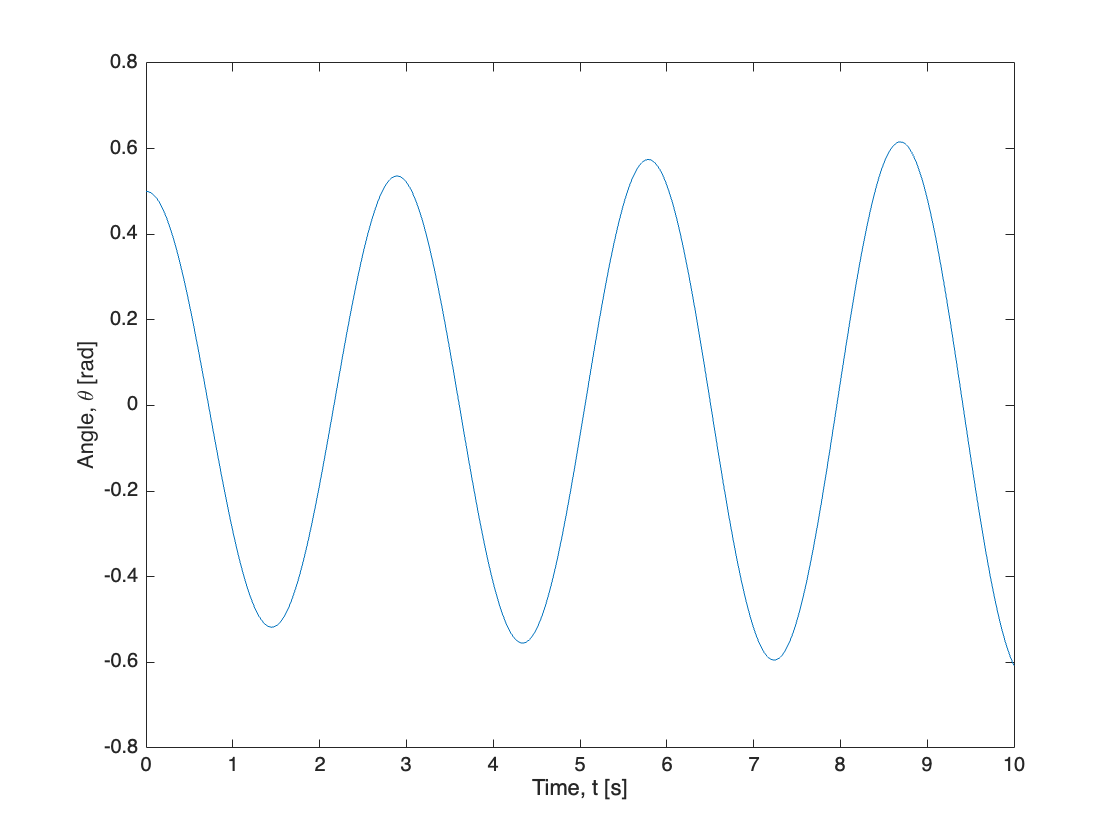

% Simple pendulum ODE
clc; clear variables; close all;

% parameters
g = 9.8;
L = 2;

% time stepping control
h = 0.01;
t = 0:h:10;
nt = length(t);

% setup result storage
theta = zeros(1, nt);
thetaDot = zeros(1, nt);

% initial conditions
theta(1) = 0.5;
thetaDot(1) = 0;

% solve intuitively using Forward Euler
for n = 1:nt-1
    theta(n+1) = theta(n) + h*thetaDot(n);
    thetaDot(n+1) = thetaDot(n) + h*(-g/L*sin(theta(n)));
end

% plot results
figure
plot(t,theta)
xlabel('Time, t [s]');
ylabel('Angle, \theta [rad]')

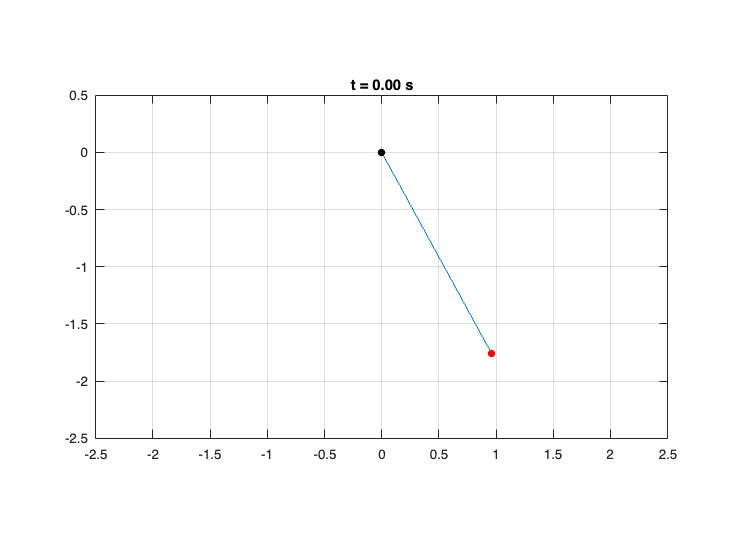

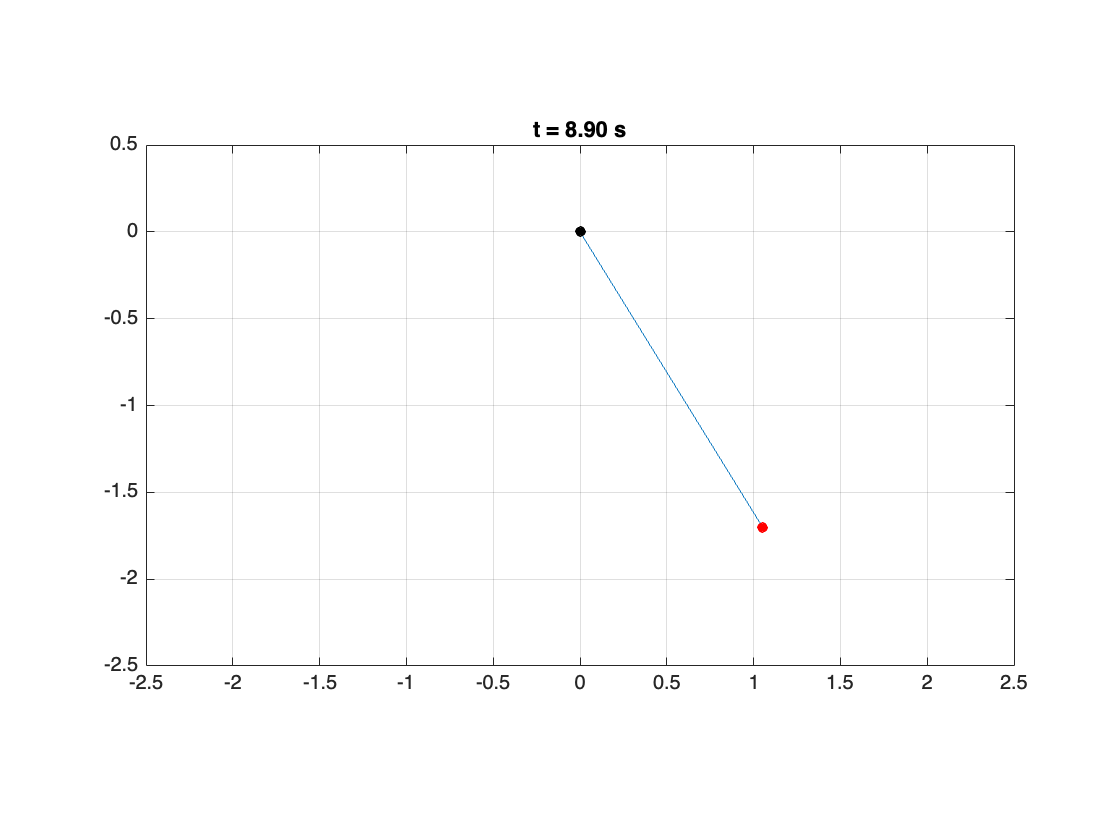


% animate pendulum
figure
for n = 1:10:nt % skip some frames so animation is faster
    x = L*sin(theta(n));
    y = -L*cos(theta(n));
    
    cla
    plot([0 x], [0 y])   % rod
    hold on
    plot(x, y, "ro", "MarkerSize", 5, "MarkerFaceColor", "r") % bob
    plot(0, 0, "ko", "MarkerSize", 5, "MarkerFaceColor", "k")  % pivot
    
    axis equal
    axis([-2.5 2.5 -2.5 0.5])
    title(sprintf("t = %.2f s", t(n)))
    grid on
    drawnow
end

**Exercise 2**

Repeat Exercise 1.

Now converting the 2nd order ODE to a system of two first order ODEs.

Put them on the standard form and use the supplied RK4 integrator, a suitable timestep ℎ that gives accuracy comparable to that of Forward Euler.

Add a drag term, $-\mu \cdot \dot{\theta}$ that kicks in at $t = 5s$.


$$\begin{array}{l}
\ddot{\theta} =-\frac{g}{l}\sin \theta -\mu \;\dot{\theta} \\
u_1 =\theta \;\;\;\Rightarrow \dot{u_1 } =u_2 \\
u_2 =\dot{\theta \;} \;\;\Rightarrow \dot{u_2 } =-\frac{g}{l}\sin \;u_1 -\mu \;u_2 
\end{array}$$


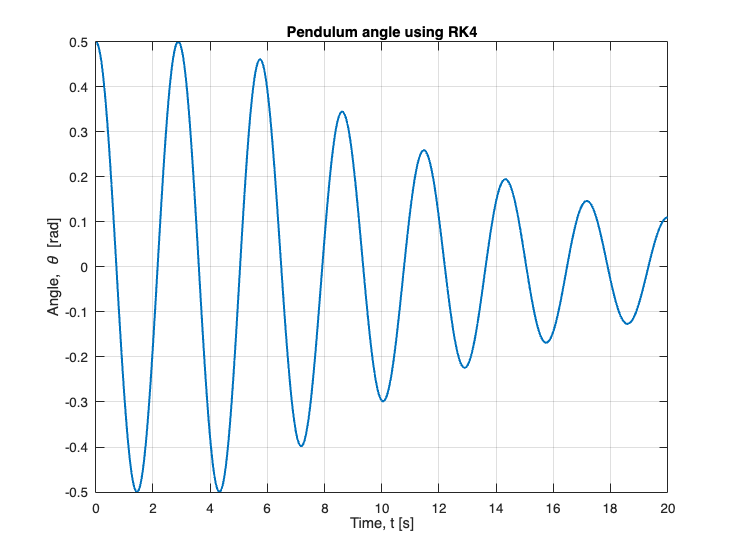

% Simple pendulum ODE solved with RK4
clc; clear variables; close all;

% parameters
g = 9.8;
L = 2;
mu0 = 0.5;              % damping coefficient after t = 5 s

% time stepping control
h = 0.05;
t = 0:h:20;

% initial conditions
Y0 = [0.5; 0];

% calling the integrator/solver
Y = odesRK4(@ode_pendulum, Y0, t);

% extract results
theta = Y(1,:);
thetaDot = Y(2,:);

% plot results
figure
plot(t, theta, 'LineWidth', 1.5)
xlabel('Time, t [s]');
ylabel('Angle, \theta [rad]')
title('Pendulum angle using RK4')
grid on

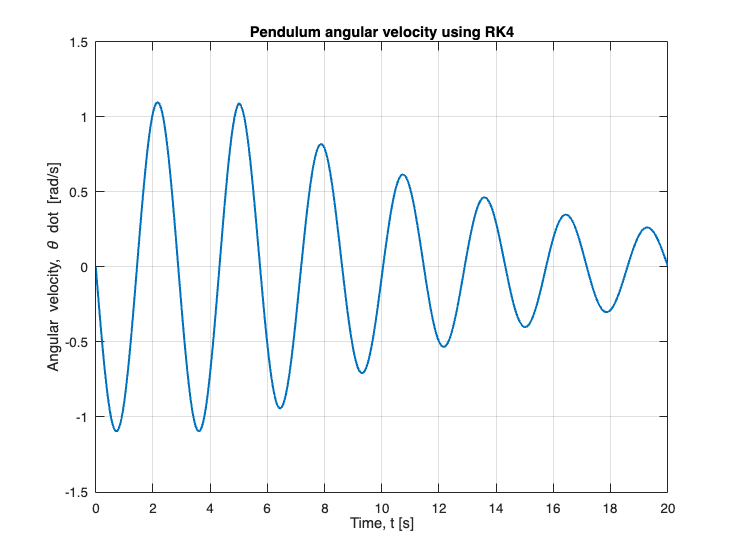


figure
plot(t, thetaDot, 'LineWidth', 1.5)
xlabel('Time, t [s]');
ylabel('Angular velocity, \theta dot [rad/s]')
title('Pendulum angular velocity using RK4')
grid on

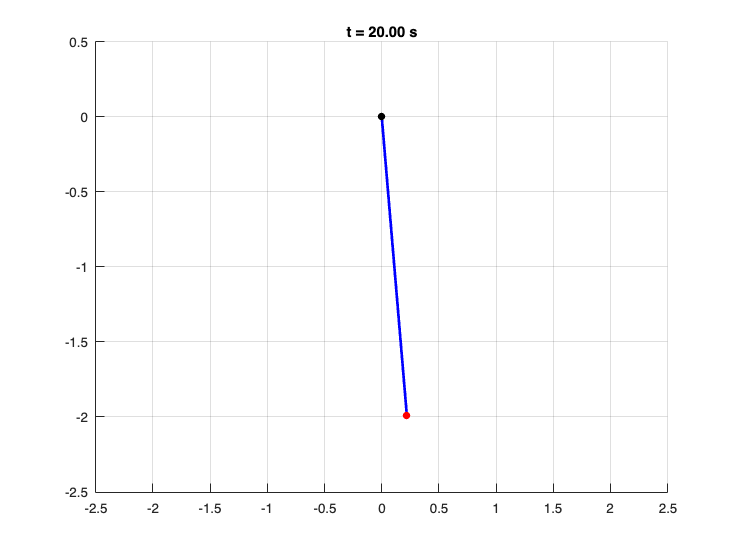


% animate pendulum
figure
axis([-2.5 2.5 -2.5 0.5])
grid on
hold on

rod = plot([0 0], [0 -L], 'b-', 'LineWidth', 2);
bob = plot(0, -L, 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'r');
pivot = plot(0, 0, 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'k');

for n = 1:2:length(t)
    x = L*sin(theta(n));
    y = -L*cos(theta(n));

    set(rod, 'XData', [0 x], 'YData', [0 y]);
    set(bob, 'XData', x, 'YData', y);
    title(sprintf('t = %.2f s', t(n)))

    drawnow
    pause(0.02)
end



function dYdt = ode_pendulum(Y, t)
    % parameters
    g = 9.8;
    L = 2;
    mu0 = 0.2;

    % unpack variables
    u1 = Y(1);   % theta
    u2 = Y(2);   % thetaDot

    % drag turns on at t = 5 s
    if t < 5
        mu = 0;
    else
        mu = mu0;
    end

    % system of first-order ODEs
    dYdt = zeros(2,1);
    dYdt(1) = u2;
    dYdt(2) = -(g/L)*sin(u1) - mu*u2;
end

**Exercise 3**

The motion of a bouncing ball can be described by

$m\;\ddot{x} =F_{i\;x} -\mu \;\dot{x}$ and $m\;\ddot{y} =-m\;g+F_{i\;y} -\mu \;\dot{y}$

- Setup $Y$ and $\frac{\textrm{dY}}{\textrm{dt}}$

- Confine the ball to a rectangular box of 10x5

- Impact forces are working opposite to the direction of penetration with magnitude $F_i =\Delta \cdot \;k$, where $k = 25000$ and $\Delta$ is the penetration of the ball into the wall/floor.

- Use constants $m = 1, \mu = 0.2$

- Initial conditions: $x_0 = 1, y_0 = 4, \dot{x}_0 = 5, \dot{y}_0 = 2$

- Simulate for 20 seconds and animate the results.

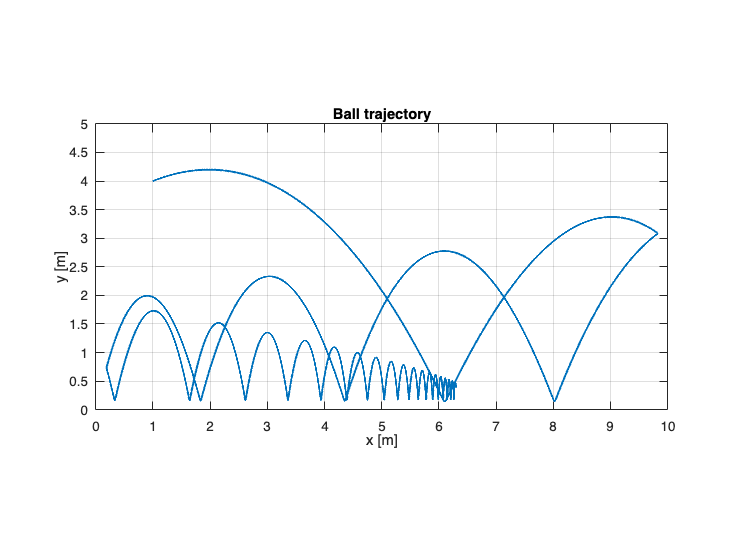

% Exercise 3 - Bouncing ball in a 10x5 box
clc; clear; close all;

% Parameters
k = 25000;
m = 1;
mu = 0.2;
g = 9.8;
r = 0.2;              % ball radius

% Time
h = 0.001;            % small timestep for stiff wall contact
t = 0:h:20;

% Initial conditions
% State vector Y = [x; y; xdot; ydot]
Y0 = [1; 4; 5; 2];

% Solve with RK4
Y = ODEsRK4(@ode_ball, Y0, t);

% Extract results
x = Y(1,:);
y = Y(2,:);
xdot = Y(3,:);
ydot = Y(4,:);

% Plot trajectory
figure
plot(x, y, 'LineWidth', 1.5)
xlabel('x [m]')
ylabel('y [m]')
title('Ball trajectory')
grid on
axis equal
xlim([0 10])
ylim([0 5])

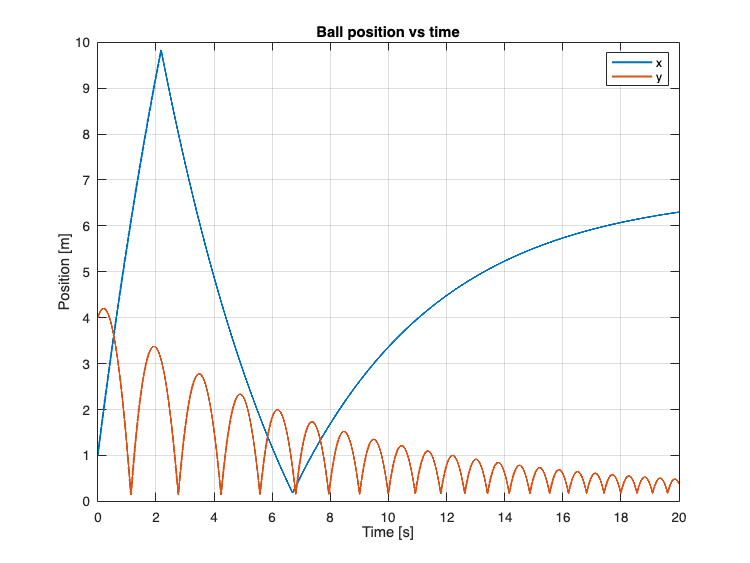


% Plot positions versus time
figure
plot(t, x, 'LineWidth', 1.5)
hold on
plot(t, y, 'LineWidth', 1.5)
xlabel('Time [s]')
ylabel('Position [m]')
legend('x', 'y')
title('Ball position vs time')
grid on

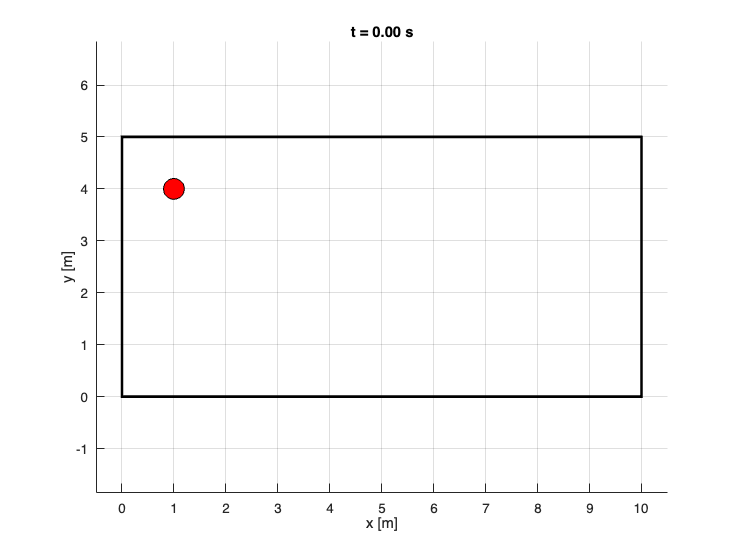

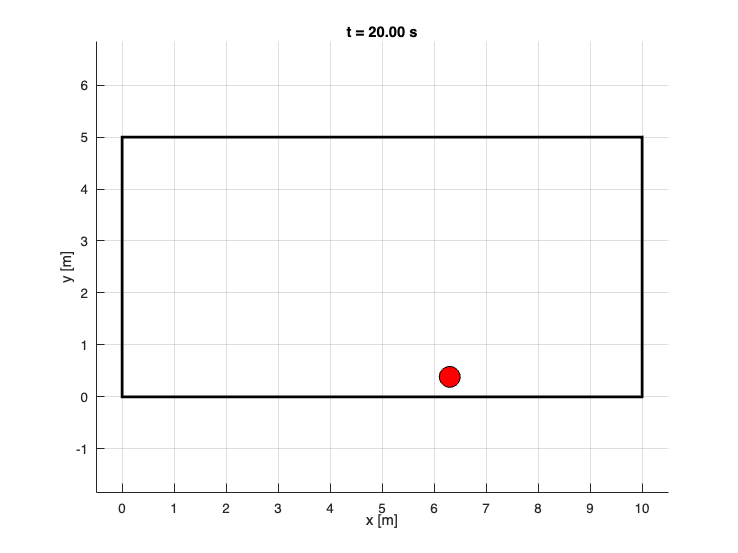


% Animate
figure
for n = 1:100:length(t)
    clf
    hold on

    % Draw box
    rectangle('Position', [0 0 10 5], 'EdgeColor', 'k', 'LineWidth', 2)

    % Draw ball as a circle
    rectangle('Position', [x(n)-r, y(n)-r, 2*r, 2*r], ...
              'Curvature', [1 1], ...
              'FaceColor', 'r', ...
              'EdgeColor', 'k')

    xlim([-0.5 10.5])
    ylim([-0.5 5.5])
    axis equal
    grid on
    xlabel('x [m]')
    ylabel('y [m]')
    title(sprintf('t = %.2f s', t(n)))

    drawnow
    pause(0.01)
end



function dYdt = ode_ball(Y, t)
    % Parameters
    k = 25000;
    m = 1;
    mu = 0.2;
    g = 9.8;
    r = 0.2;

    % Unpack state vector
    x = Y(1);
    y = Y(2);
    xdot = Y(3);
    ydot = Y(4);

    % Contact forces
    Fix = 0;
    Fiy = 0;

    % Left wall: x = r
    if x < r
        Fix = Fix + k*(r - x);
    end

    % Right wall: x = 10 - r
    if x > 10 - r
        Fix = Fix - k*(x - (10 - r));
    end

    % Floor: y = r
    if y < r
        Fiy = Fiy + k*(r - y);
    end

    % Ceiling: y = 5 - r
    if y > 5 - r
        Fiy = Fiy - k*(y - (5 - r));
    end

    % State derivative
    dYdt = zeros(4,1);
    dYdt(1) = xdot;
    dYdt(2) = ydot;
    dYdt(3) = (Fix - mu*xdot)/m;
    dYdt(4) = (-m*g + Fiy - mu*ydot)/m;
end


function Y = ODEsRK4(ODEfun, Y0, t)
    % Runge-Kutta 4th order solution of a system of ODEs

    nEq = length(Y0);
    nt = length(t);

    Y = zeros(nEq, nt);
    Y(:,1) = Y0;

    for n = 1:nt-1
        h = t(n+1) - t(n);

        k1 = h * ODEfun(Y(:,n),           t(n));
        k2 = h * ODEfun(Y(:,n)+0.5*k1,    t(n)+h/2);
        k3 = h * ODEfun(Y(:,n)+0.5*k2,    t(n)+h/2);
        k4 = h * ODEfun(Y(:,n)+k3,        t(n)+h);

        Y(:,n+1) = Y(:,n) + (1/6)*k1 + (1/3)*(k2+k3) + (1/6)*k4;
    end
end